format shortG
u = symunit;
% separateUnits(x)
% unitConvert(expr,units)

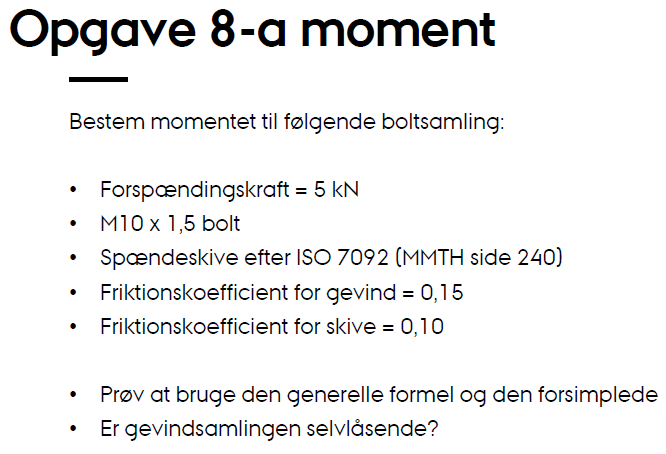

Fi = 5 * u.kN; % Forspændingskraften
d = 10 * u.mm; % spindeldiameteren
p = 1.5 * u.mm; %pitch (afstand fra top til top)
A_r = 52.3 * u.mm^2; %areal fra roddiameter se table 8-1 i shigleys eller one note
d_r = sqrt(4 * A_r / pi);% rod diameteren
d_r_ = vpa(d_r,3)

$$d\_r\_ = 8.16\,\mathrm{mm}$$

d_m = (d + d_r)/2; %middeldiameter
d_m_ = vpa(dm,3)

$$d\_m\_ = 9.08\,\mathrm{mm}$$


d_w = 1.5 * d % hvis ikke andet er opgevet

$$d\_w = 15\,\mathrm{mm}$$


d_c_min = 10.5 * u.mm; %mindste diameter på spændeskive
d_c_max = 18 * u.mm; %største diameter på spændeskive

d_c =  (d_c_min + d_c_max) / 2;%middel diameter på spændeskive
% d_c = (d + d_w) / 2

f = 0.15; %friktionskoefficienten i gevind
fc = 0.10; %friktionskoefficienten i spændeskive
alpha = 30; %grader %30 grader er den typiske vinkel

n = 1; %antal gevind start
l = p * n; %stigning r omdrejning (l = p ved n = 1)


lambda = atan(l/(pi*d_m)); %stigningsvinklen i gevind
vpa(lambda);

%funktion for forspændingsmomentet
T = (Fi*dm/2) * ((tan(lambda) + f * secd(alpha)) /...
    (1 - f * tan(lambda) * secd(alpha))) + (Fi*fc*d_c)/2;
T_ = vpa(unitConvert(T, u.N * u.m), 4)

$$T\_ = 8.735\,N\,m$$



%simpel metode ligning 8-27 eller bolt 3 side 21
% I det tilfælde af at de to 𝑓 og 𝑓𝑐 = 0,15 ender det med at 𝐾 = 0.2
T_simpel = 0.2 * Fi * d; %den reducered formel når d_c = 1.25 * d

T_simpel_ = vpa(unitConvert(T_simpel, u.N * u.m), 4)

$$T\_simpel\_ = 10.0\,N\,m$$

if f > separateUnits(tan(lambda)) %konverter fra symbol til numeric
    disp("Den er selvlåsende")
end

Den er selvlåsende


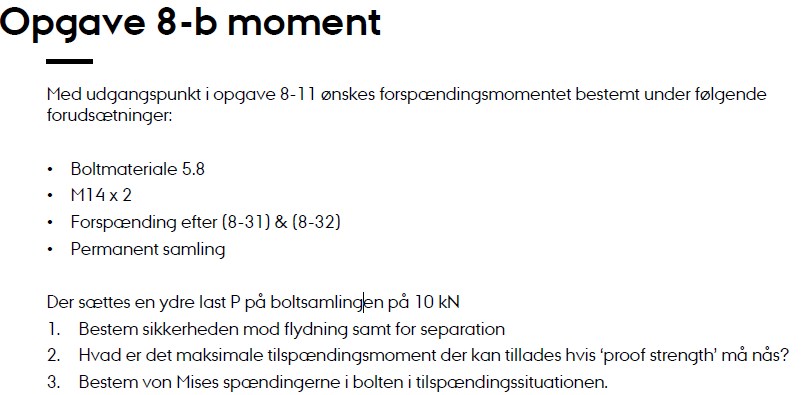

clear
format shortG
u = symunit;

d = 14 * u.mm;
H_b = 9.25 % Højde på bolt hoved (se også table A-31) [mm]

H_b =          9.25


p = 2 * u.mm;
t = 15 * u.mm;              % tykkelse af pladen [mm]
H_m = 12.8 * u.mm;             % Højde på møtrik (se også table A-29) [mm]
R = 0.6;              % Rundingsradius (se også table A-29)[mm]
E = 210 * u. GPa;
l = 2*t

$$l = 30\,\mathrm{mm}$$

alpha = 30 % - trykkegle (mellem 25 og 33 grader, shigley bruger 30 grader) - se også side 17 i bolte 2

alpha =     30


d_w =  21 * u.mm;             % Nøglevidde/Washer face (tabel A-31 se under W)

L_test = t + t + H_m;          % Gevindlængde  [mm]
L_test_ = vpa(L_test, 3)

$$L\_test\_ = 42.8\,\mathrm{mm}$$


L = 45 * u.mm

$$L = 45\,\mathrm{mm}$$


if separateUnits(L) <= 125 && separateUnits(d) <= 48
    L_T = 2*d + 6 * u.mm
elseif 125 < separateUnits(L) && separateUnits(L)<= 200
    L_T = 2 * d + 12
elseif separateUnits(L) > 200
    L_T = 2 * d + 25
else
    disp("Hmmm something is wrong")
end

$$L\_T = 34\,\mathrm{mm}$$


A_d = pi/4 * d^2;   % Skaftareal [mm^2]
A_t = 115 * u.mm^2 %pi/4 * d_t^2; % Trækspændingsareal (Se tabel 8-1) eller udregn med d_t

$$A\_t = 115\,{\mathrm{mm}}^{2}$$

l_d = L - L_T

$$l\_d = 11\,\mathrm{mm}$$

l_t = l - l_d         % Gevindlængde i indgreb  [mm]

$$l\_t = 19\,\mathrm{mm}$$


% For gevindstykket gælder
k_d = vpa(unitConvert((A_d * E) / l_d, u.MN), 5) %ligning 8-16

$$k\_d = 2938.8\,\frac{\mathrm{MN}}{m}$$




%samlede stivhed når to elementer klemme sammen
k_b = vpa(unitConvert((A_d * A_t * E) / (A_d * l_t + A_t * l_d), u.MN), 5)

$$k\_b = 887.29\,\frac{\mathrm{MN}}{m}$$



% Stivhed for matrialet
k_m = (pi * E * d * tand(alpha)) /...
    (2 * log(((l * tand(alpha) + d_w - d) * (d_w + d)) / ...
    ((l * tand(alpha) + d_w + d) * (d_w - d)) ) ); %ligning 8 -21 forudsætter at begge emner er af stål

k_m = vpa(unitConvert(k_m, u.MN), 5)

$$k\_m = 3161.5\,\frac{\mathrm{MN}}{m}$$




P = 10 * u.kN; % ydre last
S_p = 380 * u.MPa; %prof


F_p = A_t * S_p

$$F\_p = 43700\,\mathrm{MPa}\,{\mathrm{mm}}^{2}$$


F_i = 0.90 * F_p % for permenente bolte ligning (8-31)

$$F\_i = 39330\,\mathrm{MPa}\,{\mathrm{mm}}^{2}$$



%Samling stivhedskontanten
C = k_b / (k_b + k_m)

$$C = 0.21915191381674059823449205812283$$



% Spændinger i bolten kan beregnes som
% sigma_b = F_b/A_t

P_b = C * P

$$P\_b = 2.1915191381674059823449205812283\,\mathrm{kN}$$

sigma_b = (F_i) / A_t;

sigma_b_ = vpa(unitConvert(sigma_b, u.MPa), 4)

$$sigma\_b\_ = 342.0\,\mathrm{MPa}$$


F_b = F_i + P_b;
F_b_ = vpa(unitConvert(F_i + P_b, u.N), 4)

$$F\_b\_ = 41520.0\,N$$


% % Sikkerhed imod flydning
% 
n_p = vpa(unitConvert(S_p / sigma_b, 'SI'), 3) % ligning 8-28

$$n\_p = 1.11$$

% n_p = S_p * A_t / (C*P + F_i)  % ligning 8-28

%seperation så længe forspændingskraften er større end den andel af den ydre last der går i underlaget
% P_m > F_i

P_m = P*(1 - C);

% P = P_b + P_m

n_0 = vpa(unitConvert(F_i / P_m, 'SI'), 3) %sikkerhed

$$n\_0 = 5.04$$



F_max = vpa(unitConvert(A_t * S_p, u.kN), 4)

$$F\_max = 43.7\,\mathrm{kN}$$




%simpel metode ligning 8-27 eller bolt 3 side 21
% I det tilfælde af at de to 𝑓 og 𝑓𝑐 = 0,15 ender det med at 𝐾 = 0.2
T_simpel = 0.2 * F_max * d; %den reducered formel når d_c = 1.25 * d

T_simpel_ = vpa(unitConvert(T_simpel, u.N * u.m), 4)

$$T\_simpel\_ = 122.4\,N\,m$$


T_i = vpa(unitConvert(0.2 * F_i * d, u.N * u.m), 4)

$$T\_i = 110.1\,N\,m$$

W_p = pi/16 * d^3; %modstand imod torsion
W_p_ = vpa(unitConvert(W_p, u.mm), 4)

$$W\_p\_ = 538.8\,{\mathrm{mm}}^{3}$$


tau_b = T_i / W_p; % Torsionsspændinger fra forspændingsmoment
tau_b_ = vpa(unitConvert(tau_b, u.MPa), 4)

$$tau\_b\_ = 204.4\,\mathrm{MPa}$$


sigma_vm = sqrt(sigma_b^2 + 3 * tau_b_^2); % Von mises spændinger
sigma_vm_ = vpa(unitConvert(sigma_vm, u.MPa), 4)

$$sigma\_vm\_ = 492.2\,\mathrm{MPa}$$